# data analyse, draw figure

tabel_trim_no_redundant                         = readtable('trim_result_no_redundant.csv');
tabel_trim_redundant_prop                       = readtable('trim_result_redundant_prop.csv');
tabel_trim_redundant_prop_delta_e_min_power     = readtable('trim_redundant_prop_delta_e_min_power.csv');
tabel_trim_redundant_prop_delta_e_power_5load   = readtable('trim_redundant_prop_delta_e_power_5load.csv');
tabel_trim_redundant_prop_var_delta_e_U0        = readtable('trim_redundant_prop_var_delta_e_U0.csv');
tabel_trim_redundant_prop_var_delta_e_U10       = readtable('trim_redundant_prop_var_delta_e_U10.csv');
tabel_trim_redundant_prop_var_delta_e_U30       = readtable('trim_redundant_prop_var_delta_e_U30.csv');
tabel_trim_redundant_prop_var_delta_e_U45       = readtable('trim_redundant_prop_var_delta_e_U45.csv');
tabel_trim_redundant_prop_var_delta_e_U60       = readtable('trim_redundant_prop_var_delta_e_U60.csv');
tabel_trim_redundant_prop_var_delta_e_U80       = readtable('trim_redundant_prop_var_delta_e_U80.csv');
tabel_trim_redundant_prop_var_delta_e_U100      = readtable('trim_redundant_prop_var_delta_e_U100.csv');

## figure1, x:U, y:power (no redundant, with prop, with delta_e(5%))

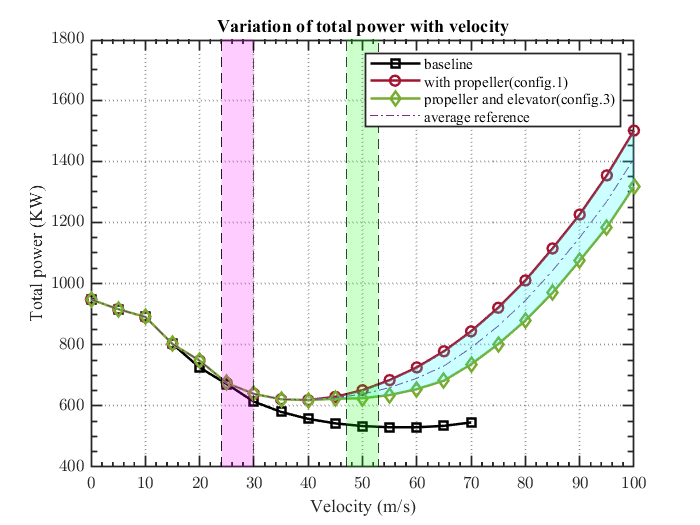

fig = figure;
ax = axes(fig);
%smooth data
x = tabel_trim_no_redundant.U(1:5:71);
y = tabel_trim_no_redundant.power_total(1:5:71)/1000;
y_smooth = smooth(x,y,0.1,'loess');
plot(ax,x,y_smooth,"LineWidth",1.5,'Color','k','Marker','square')
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.power_total(1:5:end)/1000;
y_smooth = smooth(x,y,0.1,'rloess');
data_ub = y_smooth';
plot(ax,x,y_smooth,"LineWidth",1.5,'Color','#A2142F','Marker','o')
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = tabel_trim_redundant_prop_delta_e_power_5load.power_total(1:end)/1000;
y_smooth = smooth(x,y);
y_after = [y(1:9);y_smooth(10:end)];
data_lb = y_after';
plot(ax,x,y_after,"LineWidth",1.5,'Color','#77AC30','Marker','diamond')
hold on

y = (data_ub+data_lb)/2;
plot(x,y,"-.")
hold on

axe = x';
v = [axe' data_lb';axe' data_ub'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = 'cyan';
S.FaceAlpha = 0.2;
%S.EdgeColor = 'black';
S.LineStyle = 'none';
%S.LineWidth = 0.001;
patch(ax,S)
hold on

S.Vertices = [24 0;24 2000;30 2000;30 0];
S.Faces = 1:4;
S.FaceColor = 'magenta';
S.FaceAlpha = 0.2;
S.EdgeColor = 'black';
S.LineStyle = '--';
S.LineWidth = 0.5;
patch(ax,S)
hold on

S.Vertices = [47 0;47 2000;53 2000;53 0];
S.Faces = 1:4;
S.FaceColor = 'green';
S.FaceAlpha = 0.2;
S.EdgeColor = 'black';
S.LineStyle = '--';
S.LineWidth = 0.5;
patch(S)
hold off

legend('baseline','with propeller(config.1)','propeller and elevator(config.3)','average reference');
xlabel('Velocity (m/s)'); ylabel('Total power (KW)');
title('Variation of total power with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [400 1800];

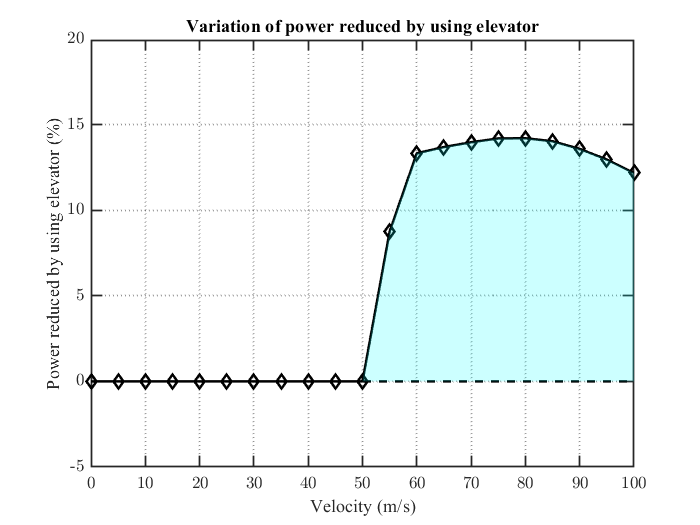


% subplot: decrease percent
fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = (tabel_trim_redundant_prop.power_total(1:5:end) - tabel_trim_redundant_prop_delta_e_power_5load.power_total)./tabel_trim_redundant_prop.power_total(1:5:end)*100;
y_smooth = smooth(x,y,3);
y_after = [y(1:11);y_smooth(12:end)];
data_ub = y_after';
h1 = plot(ax,x,y_after,"LineWidth",1.5,'Color','black','Marker','diamond');
hold on

h2 = plot(x,zeros(size(x)),"LineWidth",1.5,'Color','black','LineStyle','--');
data_lb = zeros(size(x))';
hold on

axe = x';
v = [axe' data_lb';axe' data_ub'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = 'cyan';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
patch(ax,S)
hold off

xlabel('Velocity (m/s)'); ylabel('Power reduced by using elevator (%)');
title('Variation of power reduced by using elevator');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'off';
ax.YMinorTick = 'off';
ax.TickLength(1) = 0.02;

ax.YLim = [-5,20];

## Figure2: variation of delta_e X:U, Y: delta_e

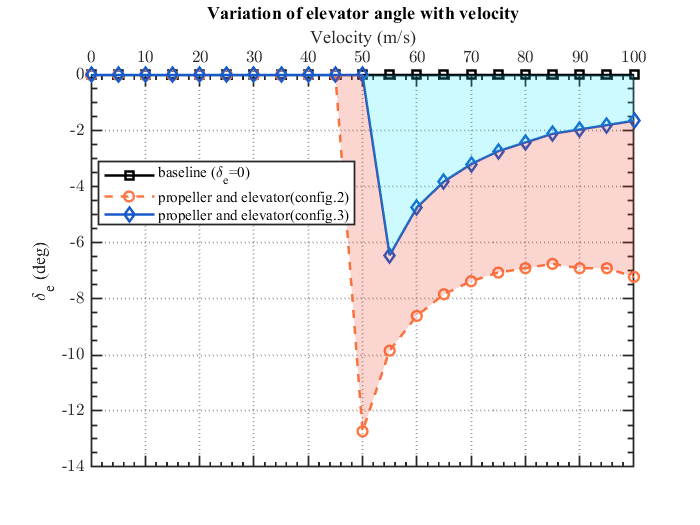

fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.delta_e(1:5:end));
data_ub1 = y';
plot(x,y,'LineWidth',1.5,"Marker","square",'Color','black')
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U(1:end);
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.delta_e);
%y_after = [];
data_lb2 = y';
plot(x,y,"LineWidth",1.5,"Marker","o",'Color','#FD7844','LineStyle',"--")
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.delta_e);
data_lb1 = y';
data_ub2 = y';
plot(x,y,"LineWidth",1.5,'Marker',"diamond",'Color','#185AC9')
hold on

axe = x';
v = [axe' data_lb1';axe' data_ub1'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = '#05E4FC';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
patch(ax,S)
hold on

axe = x';
v = [axe' data_lb2';axe' data_ub2'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = '#EC3418';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
patch(ax,S)
hold off

legend('baseline (\delta_e=0)','propeller and elevator(config.2)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('\delta_e (deg)');
title('Variation of elevator angle with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XAxisLocation = "top";
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure3a: x:U, y: rotor airload

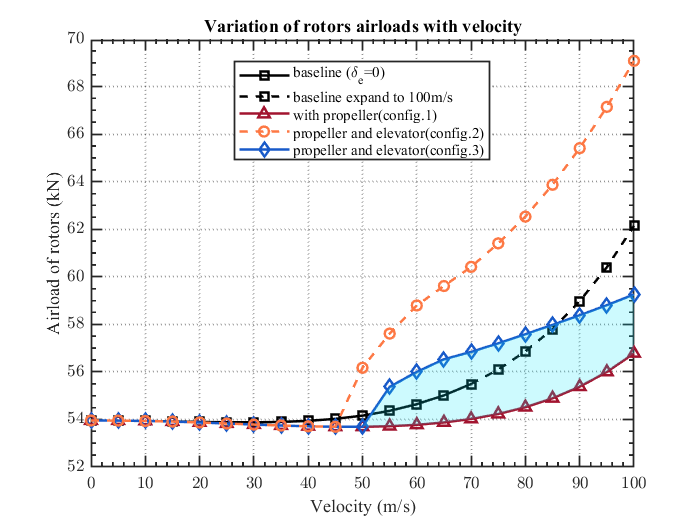

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = tabel_trim_no_redundant.T_rotor(1:5:71)/1000;
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker',"square");
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = tabel_trim_no_redundant.T_rotor(71:5:end)/1000;
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.T_rotor(1:5:end)/1000;
data_lb = y';
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker',"^");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = tabel_trim_redundant_prop_delta_e_power_5load.T_rotor(1:end)/1000;
y_smooth = smooth(x,y,0.7,'loess');
y_after = [y(1:11);y_smooth(12:end)];
data_ub = y_after';
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker',"diamond");
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U(1:end);
y = tabel_trim_redundant_prop_delta_e_min_power.T_rotor(1:end)/1000;
y_smooth = smooth(x,y,0.5,'loess');
y_after = [y(1:10);y_smooth(11:end)];
h4 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#FD7844','LineStyle','--','Marker',"o");
hold on

axe = x';
v = [axe' data_lb';axe' data_ub'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = '#05E4FC';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
patch(ax,S)
hold off

legend([h1,h11,h2,h4,h3],'baseline (\delta_e=0)','baseline expand to 100m/s','with propeller(config.1)','propeller and elevator(config.2)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('Airload of rotors (kN)');
title('Variation of rotors airloads with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## Figure 3b x:U, y: propeller thrust

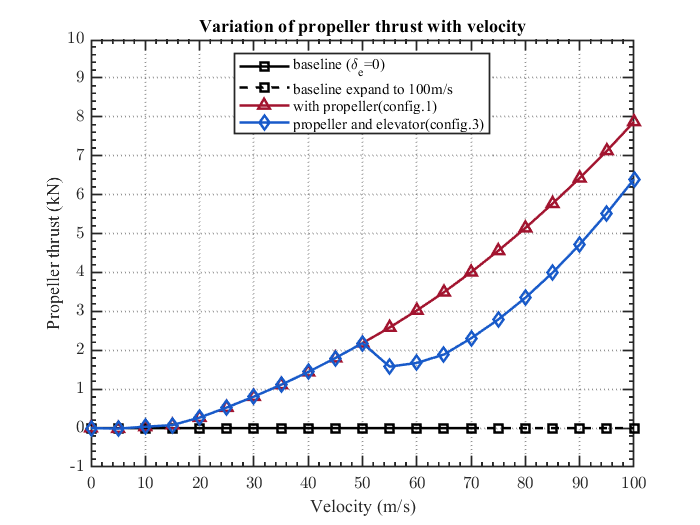

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = zeros(size(x));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker',"square");
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = zeros(size(x));
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.T_prop(1:5:end)/1000;
data_lb = y';
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker',"^");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = tabel_trim_redundant_prop_delta_e_power_5load.T_prop(1:end)/1000;
y_smooth = smooth(x,y,0.7,'loess');
y_after = [y(1:11);y_smooth(12:end)];
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker',"diamond");
hold off

legend([h1,h11,h2,h3],'baseline (\delta_e=0)','baseline expand to 100m/s','with propeller(config.1)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('Propeller thrust (kN)');
title('Variation of propeller thrust with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [-1 10];

leg = legend(ax);
leg.Location = 'best';

## Figure4: scatter X:rotor load, Y:total power

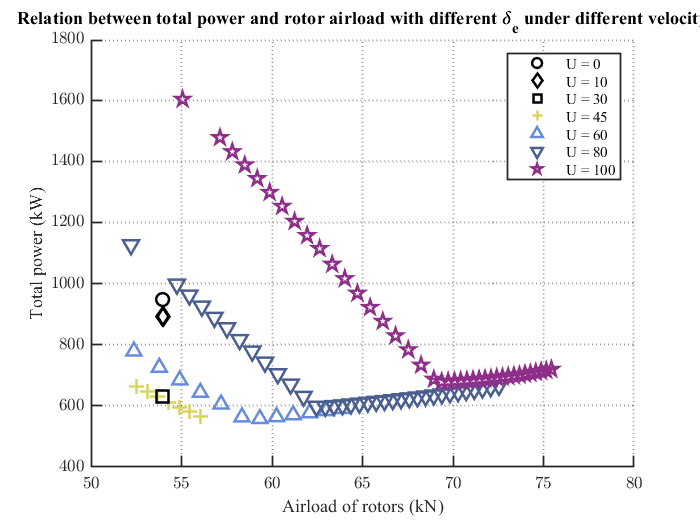

fig = figure;
ax = axes(fig);

h1 = scatter(tabel_trim_redundant_prop_var_delta_e_U0.T_rotor/1000,tabel_trim_redundant_prop_var_delta_e_U0.power_total/1000,60);
h1.Marker = "o";
h1.MarkerEdgeColor = 'black';
h1.MarkerFaceColor = 'none';
h1.LineWidth = 1.5;
hold on
h2 = scatter(tabel_trim_redundant_prop_var_delta_e_U10.T_rotor(1:20:end)/1000,tabel_trim_redundant_prop_var_delta_e_U10.power_total(1:20:end)/1000,60);
h2.Marker = "diamond";
h2.MarkerEdgeColor = 'black';
h2.MarkerFaceColor = 'none';
h2.LineWidth = 1.5;
hold on

h4 = scatter(tabel_trim_redundant_prop_var_delta_e_U45.T_rotor(1:25:end)/1000,tabel_trim_redundant_prop_var_delta_e_U45.power_total(1:25:end)/1000,80);
h4.Marker = "+";
h4.MarkerEdgeColor = '#DBD45C';
h4.LineWidth = 1.5;
h4.MarkerFaceColor = 'none';
hold on

h3 = scatter(tabel_trim_redundant_prop_var_delta_e_U30.T_rotor(1:500:end)/1000,tabel_trim_redundant_prop_var_delta_e_U30.power_total(1:500:end)/1000,80);
h3.Marker = "square";
h3.MarkerEdgeColor = 'black';
h3.MarkerFaceColor = 'none';
h3.LineWidth = 1.5;
hold on

h5 = scatter(tabel_trim_redundant_prop_var_delta_e_U60.T_rotor(1:10:end)/1000,tabel_trim_redundant_prop_var_delta_e_U60.power_total(1:10:end)/1000,60);
h5.Marker = "^";
h5.MarkerEdgeColor = '#678BDB';
h5.LineWidth = 1.5;
h5.MarkerFaceColor = 'none';
hold on

h6 = scatter(tabel_trim_redundant_prop_var_delta_e_U80.T_rotor(1:3:end)/1000,tabel_trim_redundant_prop_var_delta_e_U80.power_total(1:3:end)/1000,70);
h6.Marker = "v";
h6.MarkerEdgeColor = '#4A5F8F';
h6.LineWidth = 1.5;
h6.MarkerFaceColor = 'none';
hold on

h7 = scatter(tabel_trim_redundant_prop_var_delta_e_U100.T_rotor(1:2:end)/1000,tabel_trim_redundant_prop_var_delta_e_U100.power_total(1:2:end)/1000,80);
h7.Marker = "pentagram";
h7.MarkerEdgeColor = '#8F2E89';
h7.LineWidth = 1.5;
h7.MarkerFaceColor = 'none';
hold off

legend([h1,h2,h3,h4,h5,h6,h7],'U = 0','U = 10','U = 30','U = 45','U = 60','U = 80','U = 100');
xlabel('Airload of rotors (kN)'); ylabel('Total power (kW)');
title('Relation between total power and rotor airload with different \delta_e under different velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'off';
ax.YMinorTick = 'off';
ax.TickLength(1) = 0.02;


%leg = legend(ax);
%leg.Location = 'best';


## Figure: theta_0 X:v y:theta_0 (no ele, ele)

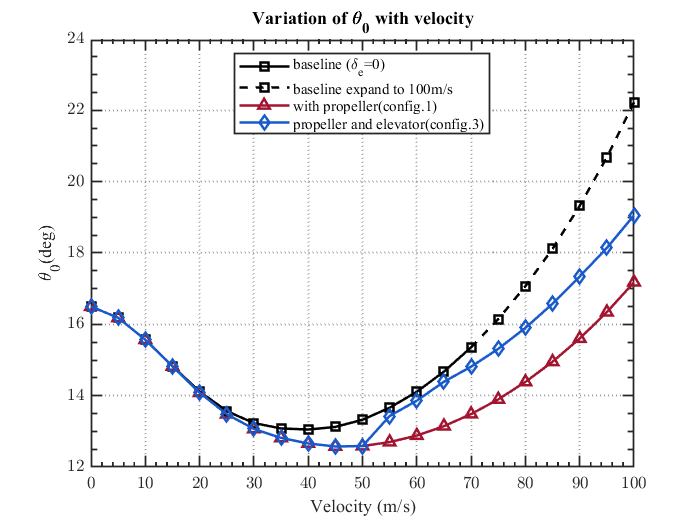

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_0(1:5:71));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_0(71:5:end));
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_0(1:5:end));
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_0);
y_smooth = smooth(x,y);
y_after = [y(1:11);y_smooth(12:end)];
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h1,h11,h2,h3],'baseline (\delta_e=0)','baseline expand to 100m/s','with propeller(config.1)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('\theta_0(deg)');
title('Variation of \theta_0 with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure theta_1c X:v y:theta_1c (no ele, ele)

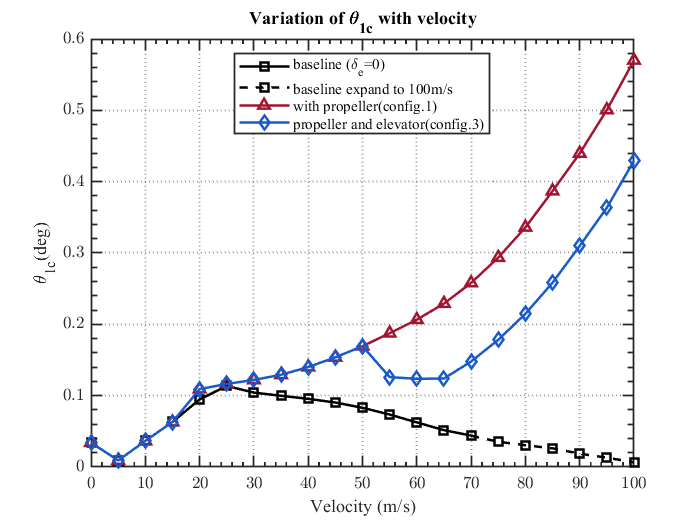

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_1c(1:5:71));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_1c(71:5:end));
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_1c(1:5:end));
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_1c);
y_smooth = smooth(x,y);
y_after = [y(1:11);y_smooth(12:end)];
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h1,h11,h2,h3],'baseline (\delta_e=0)','baseline expand to 100m/s','with propeller(config.1)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('\theta_{1c}(deg)');
title('Variation of \theta_{1c} with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure theta_1s X:v y:theta_1s (no ele, ele)

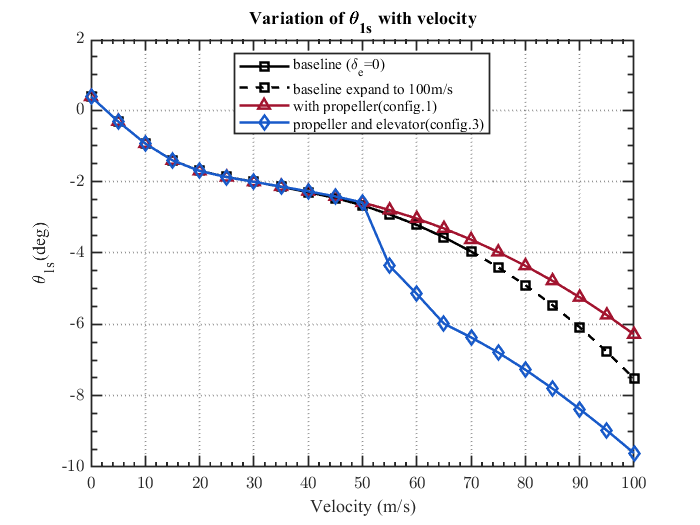

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_1s(1:5:71));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_1s(71:5:end));
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_1s(1:5:end));
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_1s);
y_smooth = smooth(x,y);
y_after = [y(1:11);y_smooth(12:end)];
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h1,h11,h2,h3],'baseline (\delta_e=0)','baseline expand to 100m/s','with propeller(config.1)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('\theta_{1s}(deg)');
title('Variation of \theta_{1s} with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure theta_diff X:v y:theta_diff (no ele, ele)

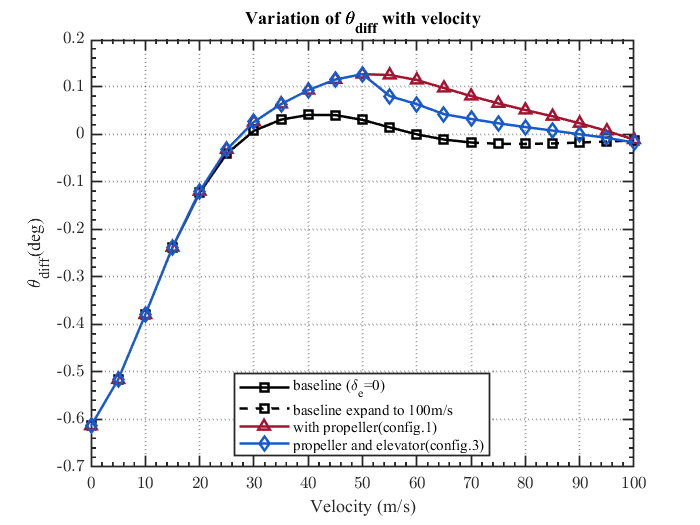

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_diff(1:5:71));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_diff(71:5:end));
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_diff(1:5:end));
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_diff);
y_smooth = smooth(x,y);
y_after = [y(1:11);y_smooth(12:end)];
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h1,h11,h2,h3],'baseline (\delta_e=0)','baseline expand to 100m/s','with propeller(config.1)','propeller and elevator(config.3)');
xlabel('Velocity (m/s)'); ylabel('\theta_{diff}(deg)');
title('Variation of \theta_{diff} with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';